## МИУ

Программа E-поляризация МИУ для 'эллипитического круглого сечения

12_12_20

close all;
clear variables;

Входные параметры

% global N a b

N = 100;

% полуоси элипса
a = 2; 
b = 1;

delta_phi = 360/N;

k = 2*pi; 
phi_grad = 90; % угол падения волны [град]

Генерация точек

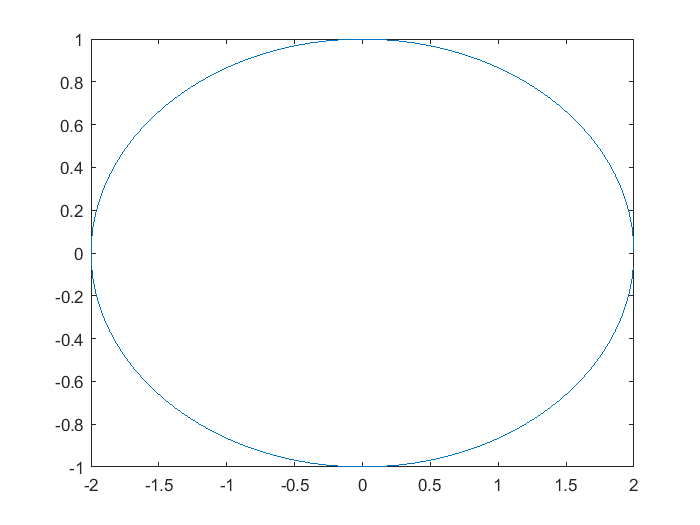

delta_phi = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    z(i) = b*sind(delta_phi*(i-1));
    x(i) = a*cosd(delta_phi*(i-1));
end

plot(x,z)

Расчет dx для каждого участка

for i = 1 : N
    if i == N
        d_x = (x(1)-x(i));
        d_z = (z(1)-z(i));
    else
        d_x = (x(i+1)-x(i));
        d_z = (z(i+1)-z(i));
    end
    
    dx(i) = sqrt(d_x^2+d_z^2);    
end


Посчитаем t для каждого отрезка

for i = 1 : N
    if i == N
        tx(i) = ((x(1)-x(i)))/dx(i);
        tz(i) = ((z(1)-z(i)))/dx(i);
    else
        tx(i) = (x(i+1)-x(i))/dx(i);
        tz(i) = (z(i+1)-z(i))/dx(i);
    end
end

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    alpha = -90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Проверка

% for i = 1 : N
%     ans(i) = dot([nx(i), nz(i)],[tx(i), tz(i)]);
% end

Координаты центров отрезков

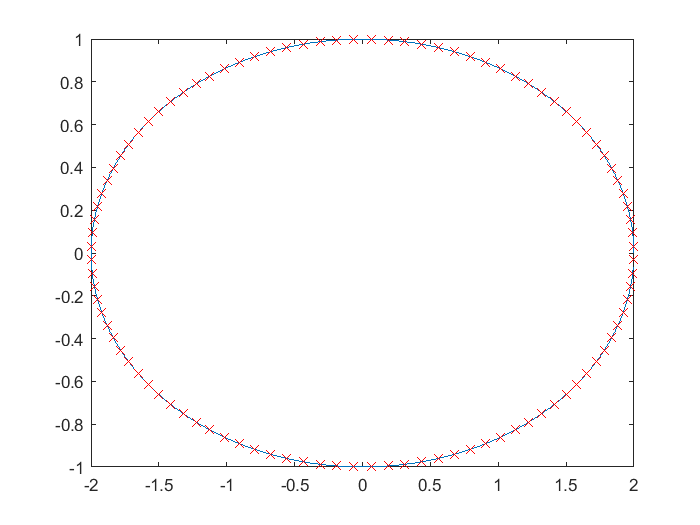

for i = 1 : N 
    if i == N
        x_midle(i) = ((x(1)+x(i)))/2;
        z_midle(i) = ((z(1)+z(i)))/2;
    else
        x_midle(i) = (x(i+1)+x(i))/2;
        z_midle(i) = (z(i+1)+z(i))/2;
    end    
end

plot(x,z,x_midle, z_midle, 'rx')

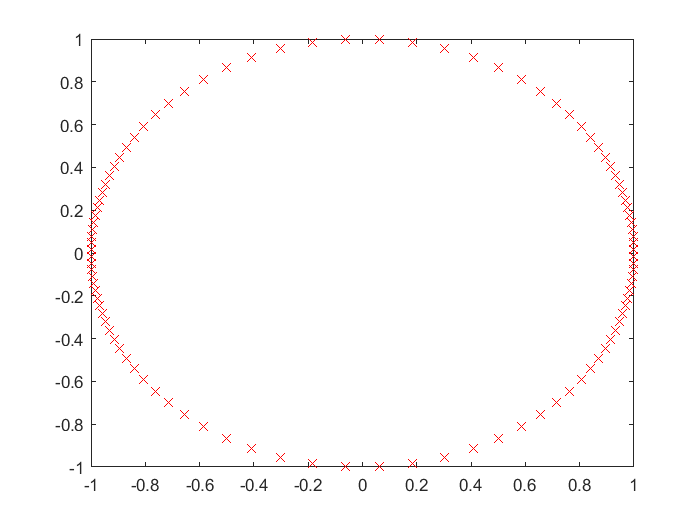


% визуализируем tx и tz
plot(tx, tz, 'rx')

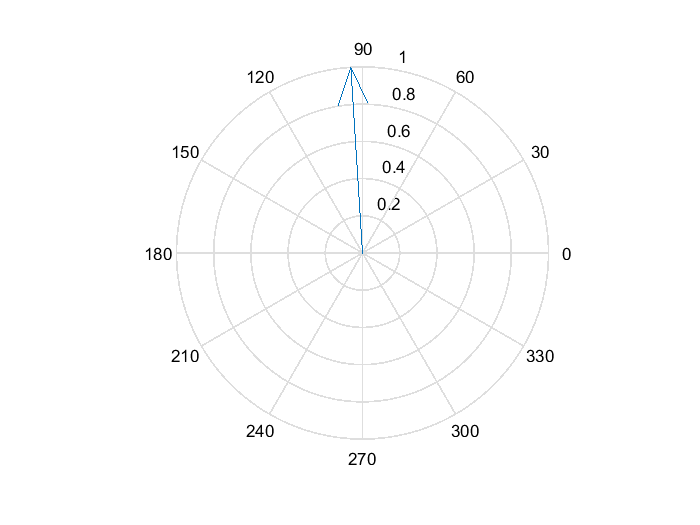

compass(tx(1),tz(1))

Порог

treshold = 1*max(dx);
% str = sprintf('Будет посчитано %.f матричных элементов через формулу',  fix(treshold/dx));
% disp(str)

% if treshold == dx
%     warning('Порог равен dx, один матричный элемен будет вычислен аналитически')    
% elseif treshold <= dx
%     warning('Порог меньше dx, ни одного матричного элемента не будет вычислено аналитически')    
%     str2 = sprintf('Порог были принят равным dx = %.i',  dx);
%     disp(str2)
%     treshold = dx;
% end

Дополнительные параметры

gamma = 1.781072417990;
delta = dx/2;

Генерация D0

for n = 1 : N
    D0(n) = k*dx(n)*(1+(1i*2/pi)*(log(gamma*k*dx(n)/4)-1));
end

Изучим один цикл

count = 0;
for m = 1 : N
    
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
    %   Координаты в исходной системе координат (в ГСК)
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);

    %   Центр новой системы кооридны - начало отрезка (в ГСК)

Давай возьмем середину отрезка

        x_begin_O2 = xn;
        z_begin_O2 = zn;
        
    %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
        x_mO2 = xm - x_begin_O2;
        z_mO2 =  zm - z_begin_O2;
         
%       Положим этот вектор на новую СК
%       Координаты этой точки (в ЛСК)
        xmO2 = x_mO2*txn + z_mO2*tzn;
        zmO2 = x_mO2*nxn + z_mO2*nzn;
           

Т.к. взяли на начало середину отрезка то тут будет

        xmnO2 = xmO2;
        zmnO2 = zmO2;

%       Растояние между m и n (в ГСК)
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
%       Расчет матричных элементов (в ЛСК)  
        if r < 0.001*dx(n) % n == m 
            Es(m,n) = D0(n);
   
        elseif  r <= treshold % abs(n - m) < 1.5
%             k_xm_plus = k*(abs(xmnO2)+delta);
%             k_xm_minus = k*(abs(xmnO2)-delta);
%             Z = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
            
%             xmn_plus_delta = (xmnO2) + delta;
%             xmn_minus_delta = (xmnO2) - delta;
%             r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
%             r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
% %             zmn = abs(zmnO2);
% %             Z = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(asin(xmn_plus_delta/r_plus_delta)- asin(xmn_minus_delta/r_minus_delta)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
%             zmn = zmnO2;
%             Z = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
            

            xmn_plus_delta = (xmnO2) + delta(n);
            xmn_minus_delta = (xmnO2) - delta(n);
            r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
            r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
            Es(m,n) = k*dx(n)+k*2*1i/pi*(dx(n)*log(gamma*k/2)-dx(n)*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx(n));

%             Es(m,n) = D1;

        else
            f2 = besselh(0,1,k*r);
            Es(m,n) = k*dx(n)*f2;
        end                    
    end
end
 

Расчет падающего поля

for m=1:N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % Определим координаты
    xm = x_midle(m);
    zm = z_midle(m);
%     txm = tx(m);
%     tzm = tz(m);
    
%   Итоговое падающее поел - это суперпозиция полей
    Ei(m,1) = +4*exp(cx*xm+cz*zm);% падающее поле X
  end

Посчитаем токи и построим график

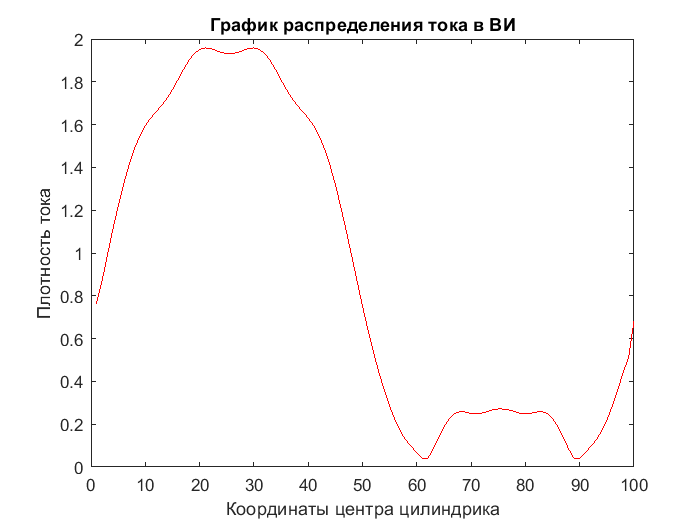

% расчеток токов ВИ 
I=Es\Ei;
       
% номера ВИ для графика 
n_for_graf = zeros(1, N);
for i = 1 : N
     n_for_graf(i) = i;
end

% построение графика респределения токов в ВИ

figure;
plot(n_for_graf, abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');

Сделаем счетчик для графика в градусах

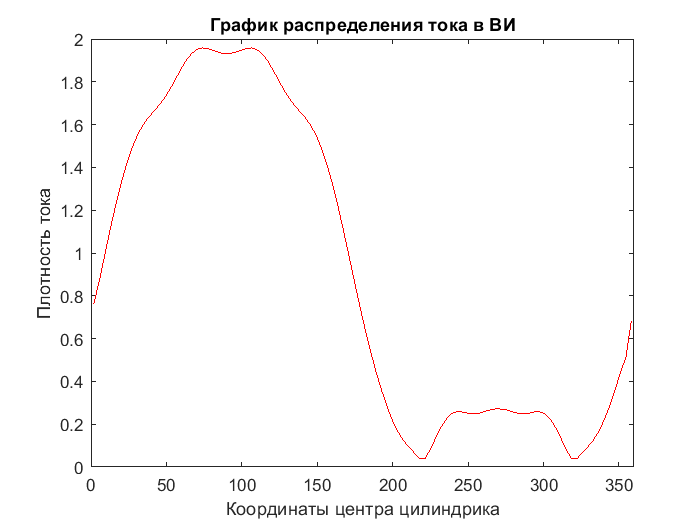

% Берем угол точки в середине отрезка
begin_phi = delta_phi/2;
phi_for_graf = [];
for i = 1 : N 
    count = begin_phi + delta_phi*(i-1);
    phi_for_graf(i) = count;
end

figure;
fig = plot(phi_for_graf, abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0 360])
ylabel('Плотность тока');

Сделаем счетчик для графика в градусах

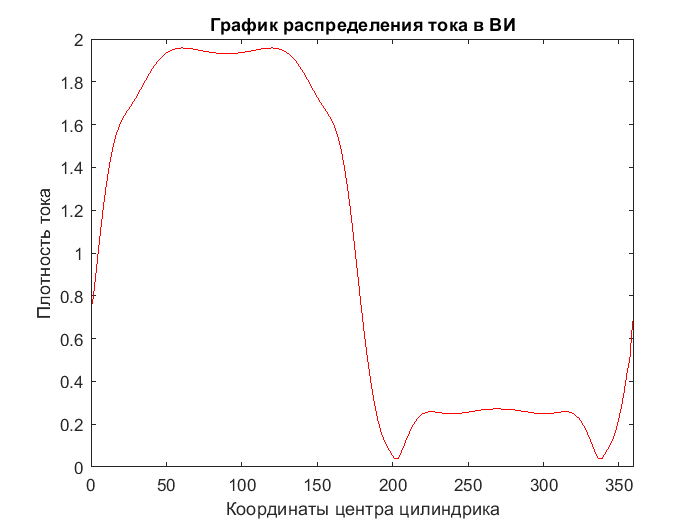

for i = 1 : N
    z_m = z_midle(i);
    x_m = x_midle(i);
    
    if (x_m <= 0 && z_m < 0) || (x_m >= 0 && z_m < 0)
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi+360;
    else
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi;
    end
end

figure;
fig = plot(phi_for_graf_real, abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0 360])
ylabel('Плотность тока');

Реальный токи

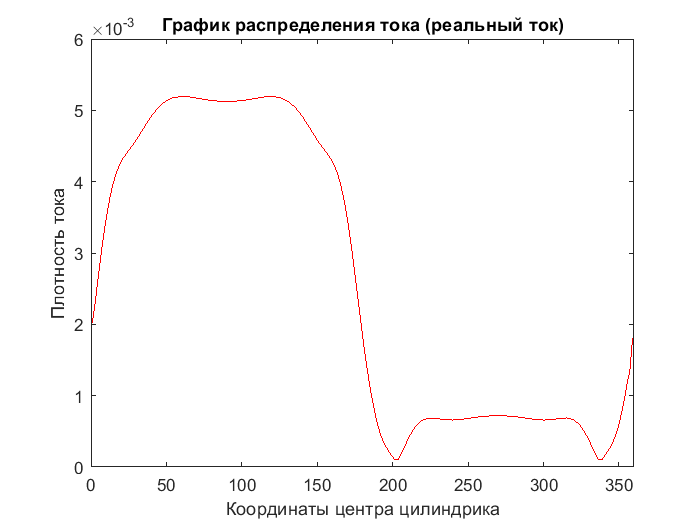

% учтем коэф мю0 который му опустили в расчетах - чтоб получить плотность тока к мА

% реальный ток в мА
I_real = I/(120*pi);

figure;
plot(phi_for_graf_real, abs(I_real), 'r');
title('График распределения тока (реальный ток)'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0,360])
ylabel('Плотность тока');

Запись в файл токов

% f01 = fopen('I_MIE_Epol_elips.dat','w');
% 
% for n=1:N
%     fprintf(f01,' %10.5f %10.5f\n', phi_for_graf_real(n), abs(I_real(n))*1000);
% end
% 
% fclose(f01);

## ЭПР

for p = 1 : 721
    Sum_E = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k*cosd(phi);
    cz = - 1i*k*sind(phi);
    

        for n = 1 : N
            txn = tx(n);
            tzn = tz(n);
            xn = x_midle(n);
            zn = z_midle(n);
            
            Sum_E = Sum_E + k*(120*pi)/4*dx(n)*I_real(n)*exp(cx*xn+cz*zn);      
        end
    
RCS(p) = 10*log10((2/pi)*Sum_E*conj(Sum_E));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA ,RCS,'r-');

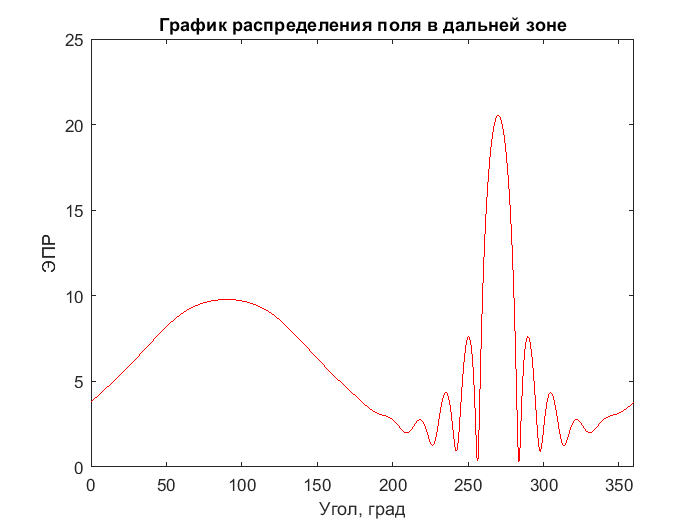

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Запись в файл ЭПР

% f02 = fopen('DA_MIE_Epol_elips.dat','w');
% for p = 1 : 721
%     fprintf(f02, ' %10.5f %10.5f\n', phi_for_graf_DA(p), RCS(p));
% end
% fclose(f02);


#### Cравнение с классом!

% ПОМЕТКА: при выборе по какой формул вычислять в исходной программе было 
%r < 0.001*dx(n) и  r <= treshold
% а я переделал на
% n == m  и  abs(n - m) < 1.5
% !!!!!!!!

calc_1 = class_MIE_EFIE_ellips_E_pol(a,b,phi_grad);
calc_1.calculate_main_ellips(N)

ans =   class_MIE_EFIE_ellips_E_pol with properties:

          ellips_main: [1×1 struct]
               I_real: []
           Sum_E_mass: []
                   DA: []
                    a: 2
                    b: 1
             phi_grad: 90
                    N: 100
                delta: [1×100 double]
                   dx: [1×100 double]
    phi_for_graf_real: NaN
      phi_for_graf_DA: NaN
                    k: 6.2832
                gamma: 1.7811


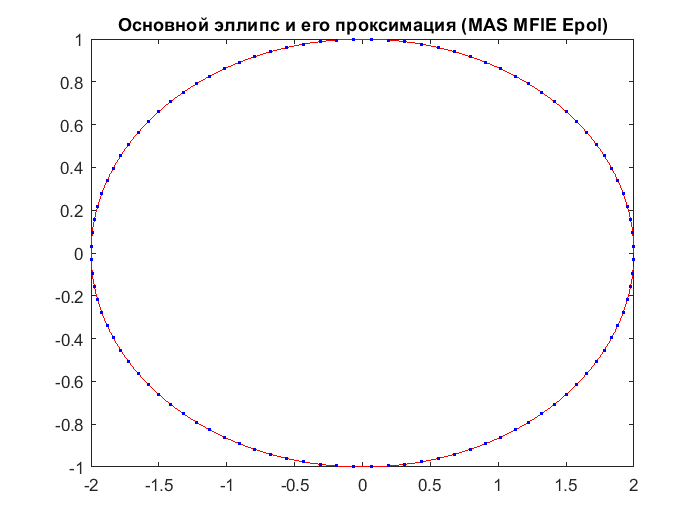

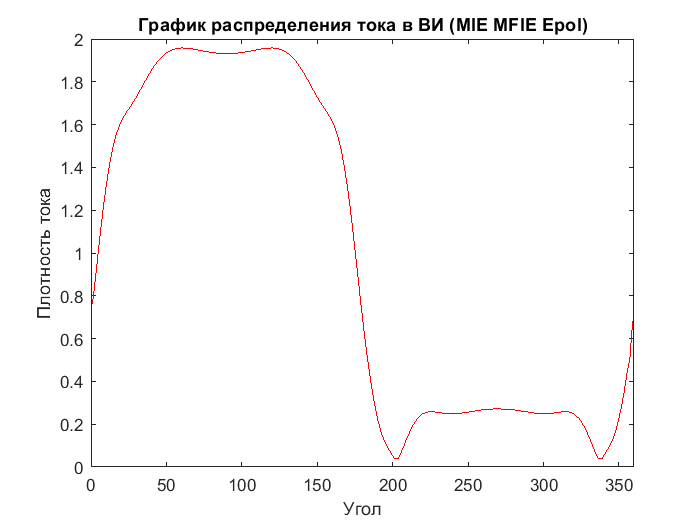

calc_1.calculate_I(N);

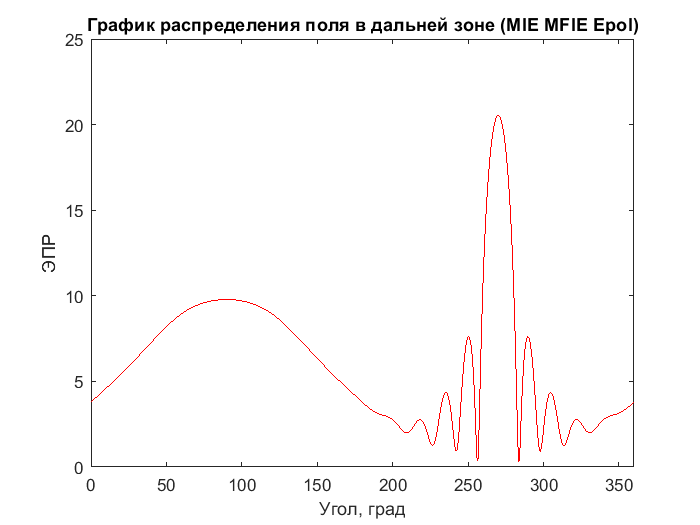

calc_1.calculate_DA();


DA_class = calc_1.get_DA

DA_class =    3.7915 + 0.0000i   3.8315 - 0.0000i   3.8717 + 0.0000i   3.9121 - 0.0000i   3.9526 + 0.0000i   3.9932 + 0.0000i   4.0338 + 0.0000i   4.0744 + 0.0000i   4.1150 - 0.0000i   4.1556 + 0.0000i   4.1962 + 0.0000i   4.2367 + 0.0000i   4.2772 + 0.0000i   4.3177 + 0.0000i   4.3581 + 0.0000i   4.3986 + 0.0000i   4.4390 + 0.0000i   4.4794 + 0.0000i   4.5198 + 0.0000i   4.5602 + 0.0000i   4.6007 + 0.0000i   4.6412 + 0.0000i   4.6818 + 0.0000i   4.7224 + 0.0000i   4.7632 + 0.0000i   4.8040 + 0.0000i   4.8450 + 0.0000i   4.8861 - 0.0000i   4.9273 + 0.0000i   4.9687 + 0.0000i   5.0102 + 0.0000i   5.0519 + 0.0000i   5.0938 + 0.0000i   5.1358 + 0.0000i   5.1781 + 0.0000i   5.2205 + 0.0000i   5.2631 + 0.0000i   5.3060 + 0.0000i   5.3490 + 0.0000i   5.3922 + 0.0000i   5.4356 + 0.0000i   5.4793 - 0.0000i   5.5231 - 0.0000i   5.5671 + 0.0000i   5.6113 + 0.0000i   5.6557 + 0.0000i   5.7003 + 0.0000i   5.7451 + 0.0000i   5.7900 - 0.0000i   5.8351 + 0.0000i


I_class = calc_1.get_I

I_class =    0.7072 + 0.2858i
   0.8515 - 0.1559i
   0.7990 - 0.5792i
   0.5196 - 0.9780i
   0.0645 - 1.2161i
  -0.4695 - 1.2337i
  -0.9734 - 1.0206i
  -1.3521 - 0.6181i
  -1.5447 - 0.1002i
  -1.5308 + 0.4477i


round(RCS,3) == round(DA_class,3)

ans = 1×721 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


round(I,3) == round(I_class,3)

ans = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
